clc, clear; 

## Exercise 8.1

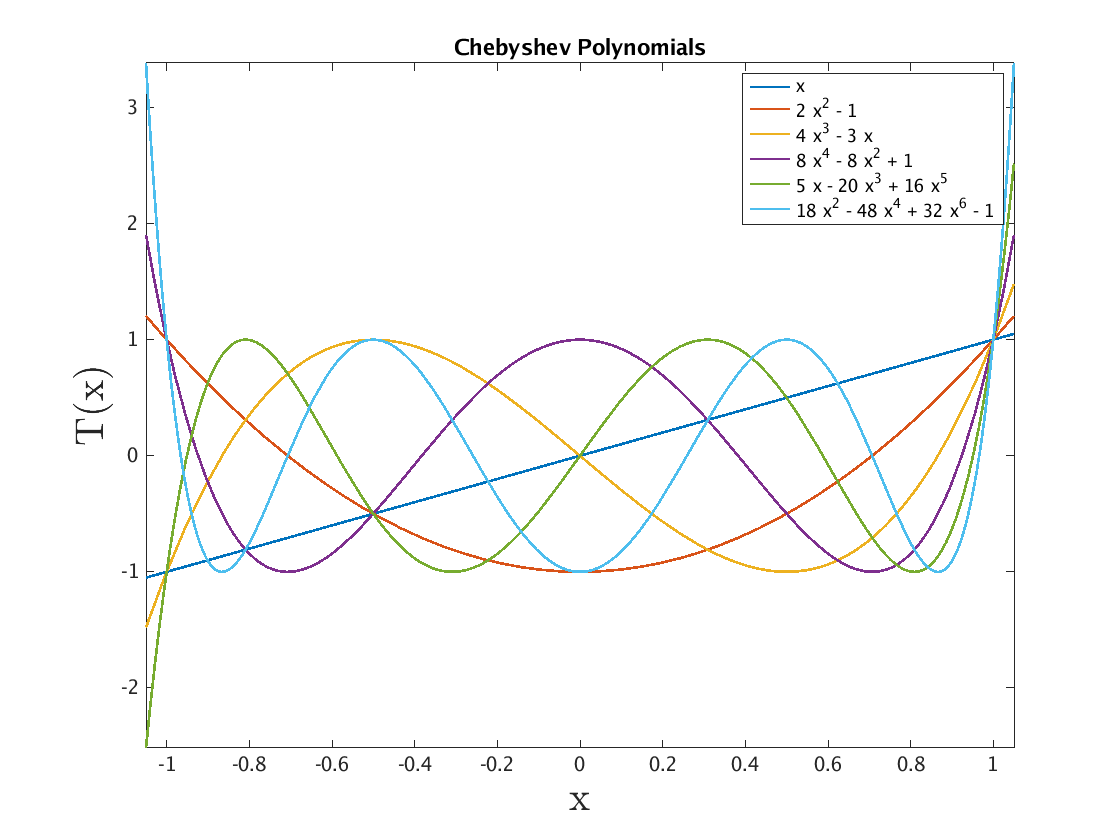

syms x 
% Used 1:6 instead of 1:10 for plot readability 
figure;
fplot(chebyshevT((1:6), x), [-1.05, 1.05], 'LineWidth', 2) 
legend('show')
title('Chebyshev Polynomials')
ylabel('T(x)','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

f = @(x) 1/(10*x^2+1);

d = zeros(1,50);
s = linspace(-1,1,200);

fn = zeros(1,200);
for i = 1: 200
    fn(1,i) = f(s(i));
end

for n = 1:50
    an = approxCheby(f, 2*n);
    yn = evalCheb(an, s);
    
    d(1,n) = max(abs(yn-fn));
end

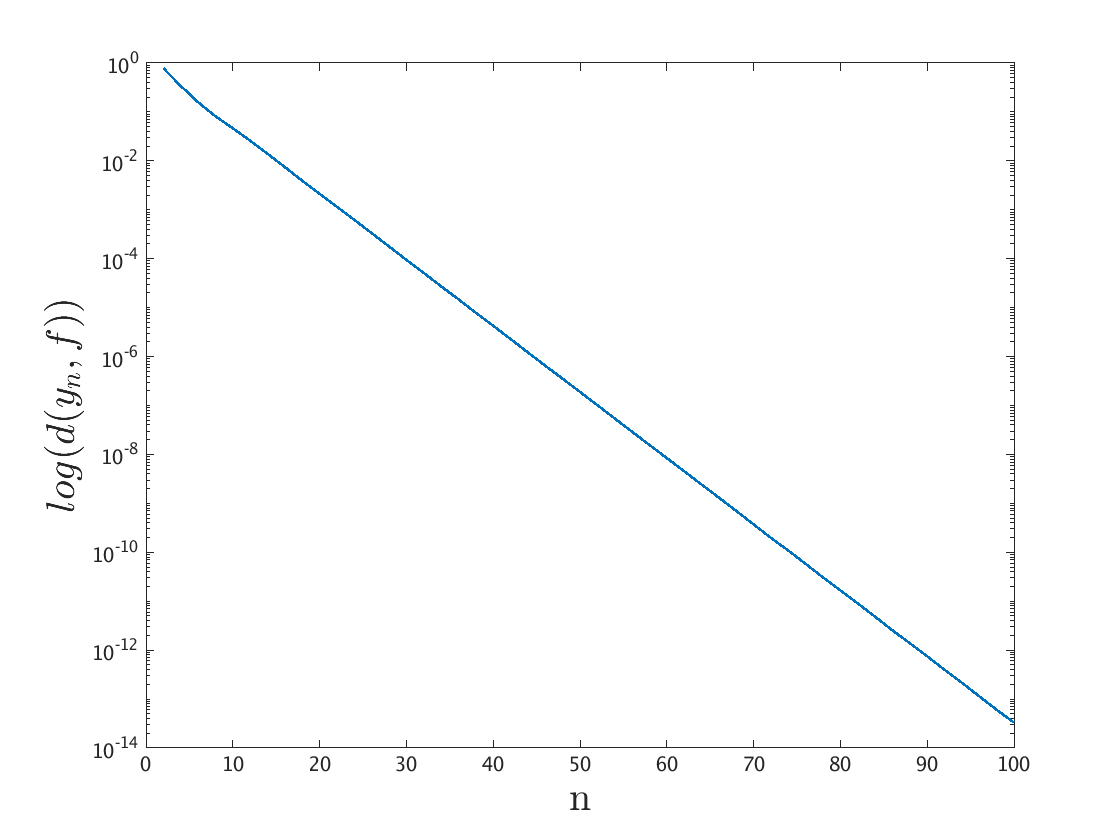

figure
semilogy([2:2:100], d, 'LineWidth', 2)
ylabel('$log(d(y_{n},f))$','Interpreter','latex', 'FontSize', 30)
xlabel('n', 'Interpreter','latex','FontSize', 30)